# Project - Stellar Motion I

- **Load the data and define the measurement parameters.**

load('live_scripts_and_data\starData.mat')
nObs = size(spectra,1)

nObs = 357

lambdaStart = 630.02

lambdaStart = 630.0200

lambdaDelta = 0.14

lambdaDelta = 0.1400

%Create vector "lambdaEnd" and store the value of the last wavelength in the recorded spectrum.
lambdaEnd = lambdaStart + (nObs - 1)*lambdaDelta

lambdaEnd = 679.8600


%Use "lambdaEnd" to get the wavelengths in the spectrum
lambda = lambdaStart:lambdaDelta:lambdaEnd

lambda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800



%Store column 2nd of spectra and store it to variable s.
s = spectra(:, 3)

s = 1.0e-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249



%Plot the graph and label the x and y axis.
plot(lambda,s, ".-")
xlabel("Wavelength")
ylabel("Intensity")

%Extract the minimum value of 's' and it's index.
[sHa, idx] = min(s)

sHa = 3.1440e-14

idx = 188


%use the index of the minimum value of 's' to get the wavelength of the
%hydrogen-alpha.
lambdaHa = lambda(idx)

lambdaHa = 656.2000

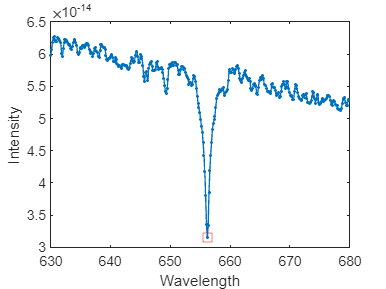


hold on
%add the point to the existing axis by using the minimum values of 's' and
%the wavwlength of the hydrogen-alpha.
plot(lambdaHa, sHa, 'rs', "MarkerSize", 8)
hold off


%Get the redshift factor and the speed (in km/s) at which the star is moving away from Earth.
speed_of_light = 299792.458;
z = (lambdaHa/656.28) - 1

z = -1.2190e-04

speed = z * speed_of_light

speed = -36.5445